clear all

% ---- Tiefpass-Teil ----
% Gegebene Werte für Tiefpass
R1_Tiefpass = 6.8e3; % Ohm
R2_Tiefpass = 68e3; % Ohm
R3_Tiefpass = 33e3; % Ohm
C1_Tiefpass = 330e-12; % Farad
C2_Tiefpass = 150e-12; % Farad
C3_Tiefpass = 22e-12; % Farad
zeta_Tiefpass = 1; % Angenommener Wert für das Dämpfungsverhältnis

% Symbolische Variable s definieren
s = tf('s');

% Cut-off Frequenzen für Tiefpass berechnen
fc1_Tiefpass = 1 / (2 * pi * R1_Tiefpass * C1_Tiefpass);
fc2_Tiefpass = 1 / (2 * pi * sqrt(R2_Tiefpass * R3_Tiefpass * C2_Tiefpass * C3_Tiefpass));

disp(['fc1_Tiefpass: ', num2str(fc1_Tiefpass), ' Hz']);

fc1_Tiefpass: 70924.6627 Hz


disp(['fc2_Tiefpass: ', num2str(fc2_Tiefpass), ' Hz']);

fc2_Tiefpass: 58485.9752 Hz



% Tiefpass-Übertragungsfunktionen definieren
% RC Tiefpass
T_RC_Tiefpass = 1 / (1 + s / (2 * pi * fc1_Tiefpass));

% Sallen-Key Tiefpass
T_SK_Tiefpass = (2 * pi * fc2_Tiefpass)^2 / (s^2 + s * 2 * pi * fc2_Tiefpass * 2 * zeta_Tiefpass + (2 * pi * fc2_Tiefpass)^2);

% Gesamtübertragungsfunktion für Tiefpass berechnen
Gesamt_Tiefpass = T_RC_Tiefpass * T_SK_Tiefpass

Gesamt_Tiefpass =
 
                   6.018e16
  ------------------------------------------
  s^3 + 1.181e06 s^2 + 4.626e11 s + 6.018e16
 
Continuous-time transfer function.



% ---- Hochpass-Teil ----
% Gegebene Werte für Hochpass
R1_Hochpass = 4.3e3; % Ohm
R2_Hochpass = 22e3; % Ohm
R3_Hochpass = 100e3; % Ohm
C1_Hochpass = 680e-12; % Farad
C2_Hochpass = 68e-12; % Farad
C3_Hochpass = 68e-12; % Farad
zeta_Hochpass = 0.707; % Angenommener Wert für das Dämpfungsverhältnis

% Cut-off Frequenzen für Hochpass berechnen
fc1_Hochpass = 1 / (2 * pi * R1_Hochpass * C1_Hochpass);
fc2_Hochpass = 1 / (2 * pi * sqrt(R2_Hochpass * R3_Hochpass * C2_Hochpass * C3_Hochpass));

disp(['fc1_Hochpass: ', num2str(fc1_Hochpass), ' Hz']);

fc1_Hochpass: 54430.5551 Hz


disp(['fc2_Hochpass: ', num2str(fc2_Hochpass), ' Hz']);

fc2_Hochpass: 49899.9234 Hz



% Hochpass-Übertragungsfunktionen definieren
% RC Hochpass
H_RC_Hochpass = s / (s + 2 * pi * fc1_Hochpass);
% Sallen-Key Hochpass
H_SK_Hochpass = s^2 / (s^2 + s * 2 * pi * fc2_Hochpass * 2 * zeta_Hochpass + (2 * pi * fc2_Hochpass)^2);

% Gesamtübertragungsfunktion für Hochpass berechnen
Gesamt_Hochpass = H_RC_Hochpass * H_SK_Hochpass

Gesamt_Hochpass =
 
                     s^3
  ------------------------------------------
  s^3 + 7.853e05 s^2 + 2.499e11 s + 3.362e16
 
Continuous-time transfer function.



% ---- Bandpass-Teil ----
% Berechnung der Gesamtübertragungsfunktion für den Bandpass
Gesamt_Bandpass = Gesamt_Tiefpass * Gesamt_Hochpass

Gesamt_Bandpass =
 
                                       6.018e16 s^3
  --------------------------------------------------------------------------------------
  s^6 + 1.966e06 s^5 + 1.64e12 s^4 + 7.521e17 s^3 + 2.026e23 s^2 + 3.059e28 s + 2.023e33
 
Continuous-time transfer function.




% Übertragungsfunktionen anzeigen
disp('Gesamtübertragungsfunktion Bandpass:');

Gesamtübertragungsfunktion Bandpass:


disp(Gesamt_Bandpass);

  tf with properties:

       Numerator: {[0.0000e+000 0.0000e+000 0.0000e+000 60.1784e+015 0.0000e+000 0.0000e+000 … ]}
     Denominator: {[1.0000e+000 1.9659e+006 1.6396e+012 752.1124e+015 202.5529e+021 30.5905e+027 … ]}
        Variable: 's'
         IODelay: 0.0000e+000
      InputDelay: 0.0000e+000
     OutputDelay: 0.0000e+000
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0.0000e+000
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]


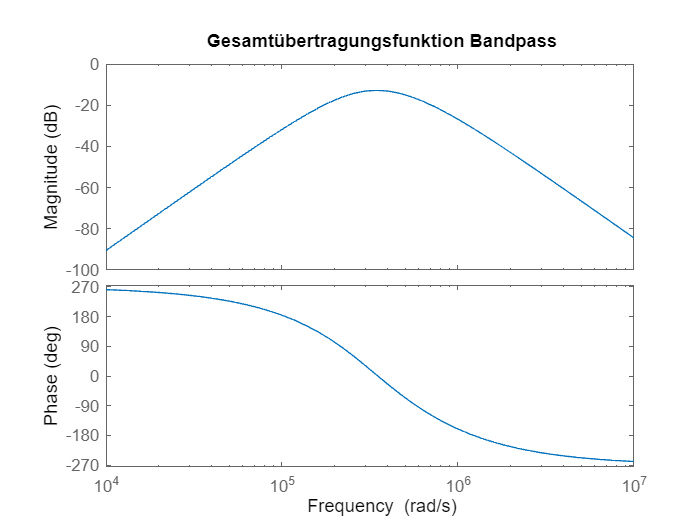


% Bode-Diagramm für Bandpass zeichnen
figure;
bode(Gesamt_Bandpass);
title('Gesamtübertragungsfunktion Bandpass');

Bode TP 1ste Ordnung


[Ziel_Coeff_Za_TP1,Ziel_Coeff_Ne_TP1] = butter(1,3,'low', 's');
Ziel_Coeff_Ne_TP1 = Ziel_Coeff_Ne_TP1 / Ziel_Coeff_Za_TP1(2);
Ziel_Coeff_Za_TP1 = Ziel_Coeff_Za_TP1 / Ziel_Coeff_Za_TP1(2);

f_von_p_TP1 = tf(Ziel_Coeff_Za_TP1, Ziel_Coeff_Ne_TP1)

f_von_p_TP1 =
 
       1
  ------------
  0.3333 s + 1
 
Continuous-time transfer function.



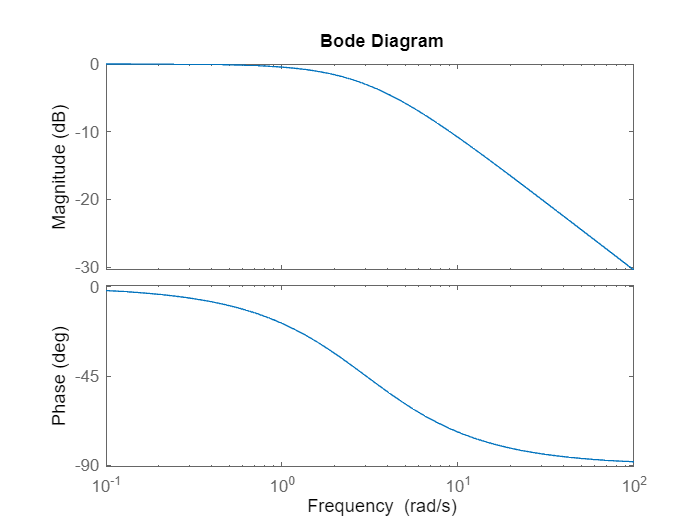


BodeDgrTP1 = bodeplot(f_von_p_TP1); 

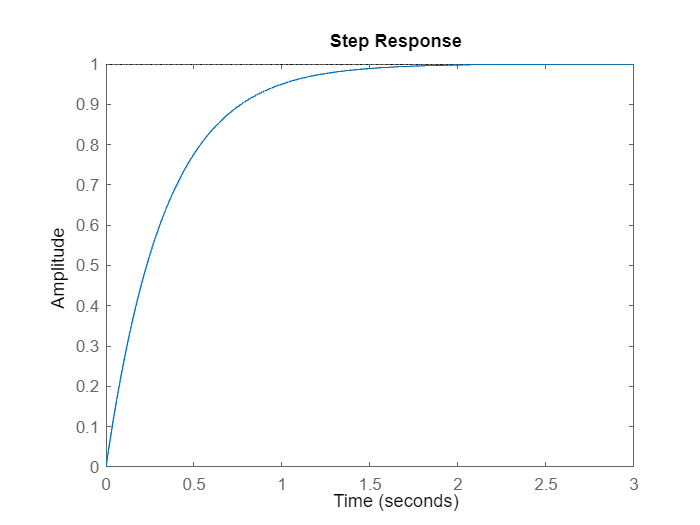



step(f_von_p_TP1); %Einschaltverhalten

Bode TP 2er Ordnung

[Ziel_Coeff_Za_TP2,Ziel_Coeff_Ne_TP2] = cheby1(2,3,314159.265,'low', 's');
Ziel_Coeff_Za_TP2 = Ziel_Coeff_Za_TP2 / Ziel_Coeff_Ne_TP2(3);
Ziel_Coeff_Ne_TP2 = Ziel_Coeff_Ne_TP2 / Ziel_Coeff_Ne_TP2(3);


f_von_p_TP2 = tf(Ziel_Coeff_Za_TP2,Ziel_Coeff_Ne_TP2)

f_von_p_TP2 =
 
             0.7079
  -----------------------------
  1.431e-11 s^2 + 2.9e-06 s + 1
 
Continuous-time transfer function.



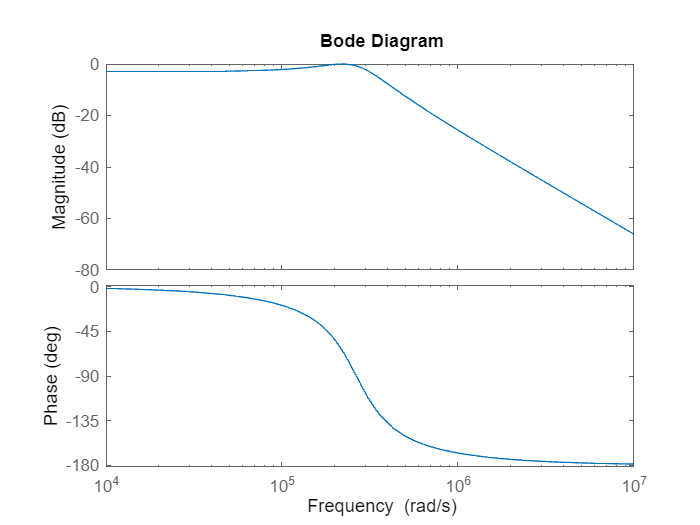


BodeDgrTP2 = bodeplot(f_von_p_TP2); 

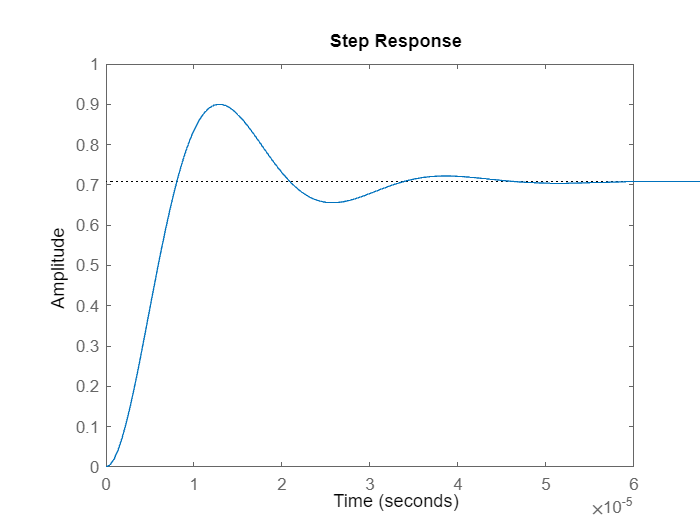


step(f_von_p_TP2); %Einschaltverhalten

TP3

[Ziel_Coeff_Za_TP3,Ziel_Coeff_Ne_TP3] = cheby1(3,1,314159.265,'low', 's');
Ziel_Coeff_Ne_TP3 = Ziel_Coeff_Ne_TP3 / Ziel_Coeff_Za_TP3(4);  % (4) zur sicherheit, wegen Format
Ziel_Coeff_Za_TP3 = Ziel_Coeff_Za_TP3 / Ziel_Coeff_Za_TP3(4);

f_von_p_TP3 = tf(Ziel_Coeff_Za_TP3,Ziel_Coeff_Ne_TP3)

f_von_p_TP3 =
 
                         1
  -----------------------------------------------
  6.564e-17 s^3 + 2.038e-11 s^2 + 8.023e-06 s + 1
 
Continuous-time transfer function.



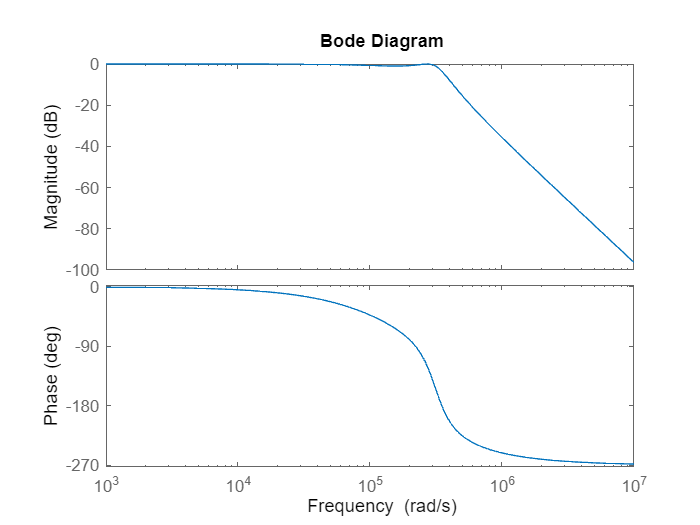


BodeDgrTP3 = bodeplot(f_von_p_TP3); 

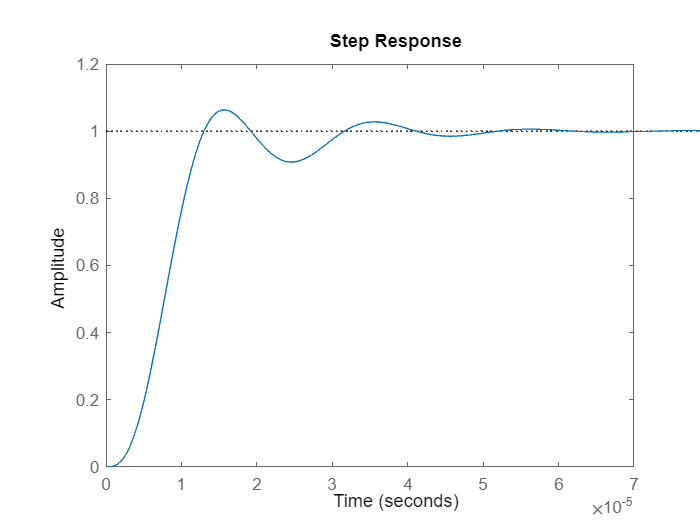


step(f_von_p_TP3); %Einschaltverhalten

Bode HP 1ste Ordnung


[Ziel_Coeff_Za_HP1,Ziel_Coeff_Ne_HP1] = butter(1,3,'high', 's');
Ziel_Coeff_Ne_HP1 = Ziel_Coeff_Ne_HP1 / Ziel_Coeff_Ne_HP1(2)

Ziel_Coeff_Ne_HP1 =    333.3333e-003     1.0000e+000


Ziel_Coeff_Za_HP1 = Ziel_Coeff_Za_HP1 / Ziel_Coeff_Ne_HP1(2) 

Ziel_Coeff_Za_HP1 =      1.0000e+000     0.0000e+000



f_von_p_HP1 = tf(Ziel_Coeff_Za_HP1,Ziel_Coeff_Ne_HP1)

f_von_p_HP1 =
 
       s
  ------------
  0.3333 s + 1
 
Continuous-time transfer function.



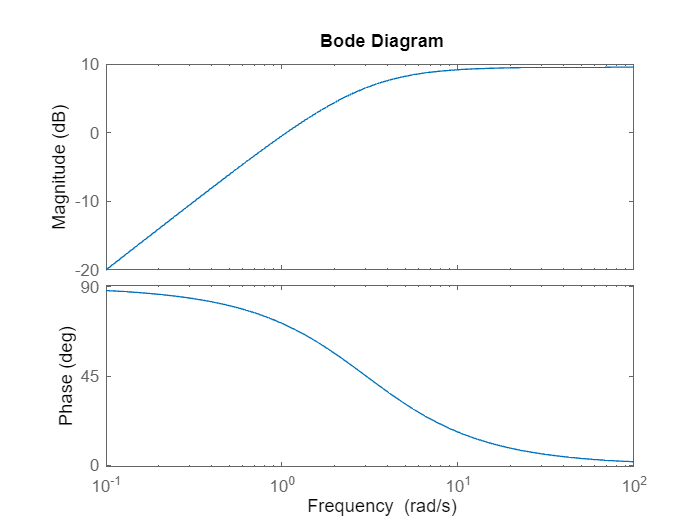


BodeDgrHP1 = bodeplot(f_von_p_HP1); 

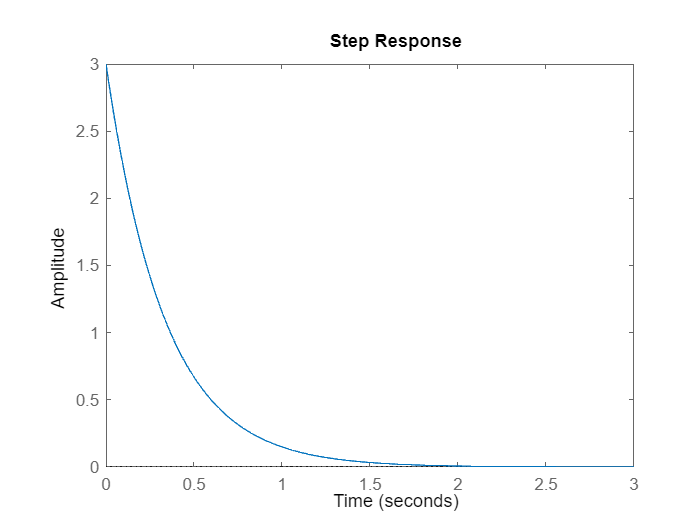


step(f_von_p_HP1); %Einschaltverhalten

Bode HP 2er Ordnung 

[Ziel_Coeff_Zae_HP2, Ziel_Coeff_Ne_HP2] = cheby1(2,3,314159.265,'high', 's');
Ziel_Coeff_Zae_HP2 = Ziel_Coeff_Zae_HP2 / Ziel_Coeff_Ne_HP2(3); 
Ziel_Coeff_Ne_HP2 = Ziel_Coeff_Ne_HP2 / Ziel_Coeff_Ne_HP2(3);
f_von_p_HP2 = tf(Ziel_Coeff_Zae_HP2,Ziel_Coeff_Ne_HP2)

f_von_p_HP2 =
 
           5.078e-12 s^2
  -------------------------------
  7.173e-12 s^2 + 2.053e-06 s + 1
 
Continuous-time transfer function.



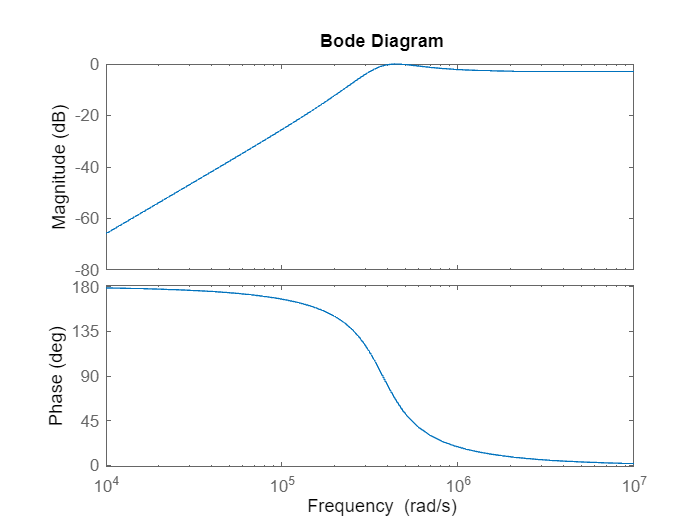


BodeDgr1HP2 = bodeplot(f_von_p_HP2); 

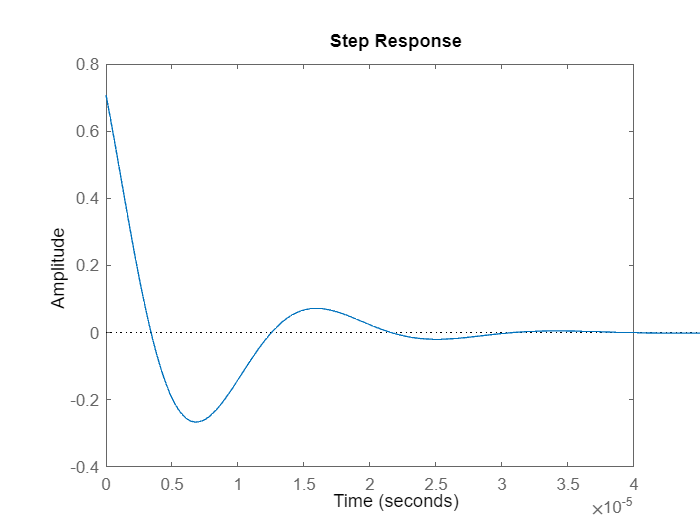


step(f_von_p_HP2); %Einschaltverhalten

HP3

[Ziel_Coeff_Zae_HP3, Ziel_Coeff_Ne_HP3] = cheby1(3,1,314159.265,'high', 's');
Ziel_Coeff_Zae_HP3 = Ziel_Coeff_Zae_HP3 / Ziel_Coeff_Ne_HP3(4);
Ziel_Coeff_Ne_HP3 = Ziel_Coeff_Ne_HP3 / Ziel_Coeff_Ne_HP3(4);
f_von_p_HP3 = tf(Ziel_Coeff_Zae_HP3,Ziel_Coeff_Ne_HP3)

f_von_p_HP3 =
 
                   1.585e-17 s^3
  -----------------------------------------------
  1.585e-17 s^3 + 1.255e-11 s^2 + 3.146e-06 s + 1
 
Continuous-time transfer function.



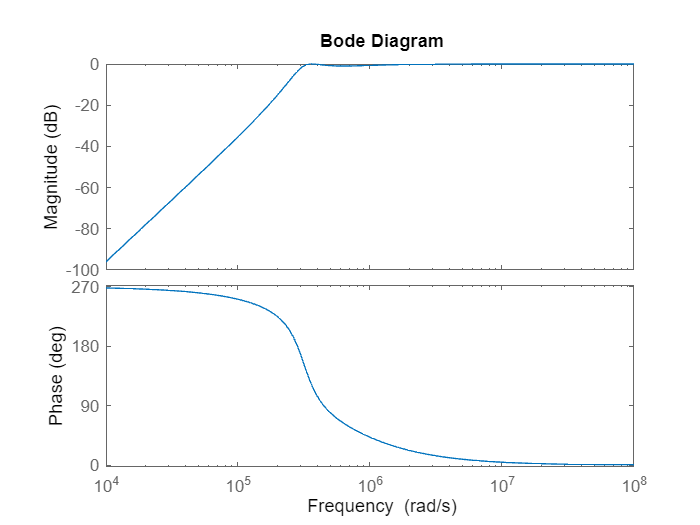


BodeDgr1HP3 = bodeplot(f_von_p_HP3); 

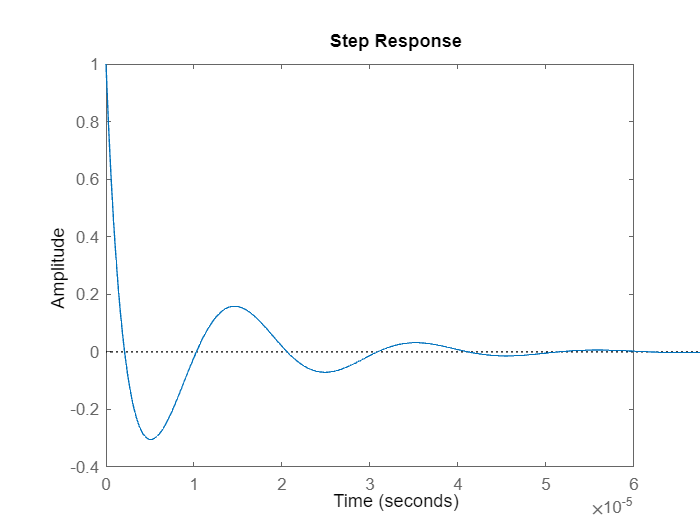


step(f_von_p_HP3); %Einschaltverhalten

Bode TP*HP

Test2 = f_von_p_TP3*f_von_p_HP3

Test2 =
 
                                                      
                                         1.585e-17 s^3
                                                      
  --------------------------------------------------------------------------------------------
                                                                                              
  1.04e-33 s^6 + 1.147e-27 s^5 + 5.894e-22 s^4 + 2.463e-16 s^3 + 5.817e-11 s^2 + 1.117e-05 s  
                                                                                              
                                                                                           + 1
                                                                                              
 
Continuous-time transfer function.



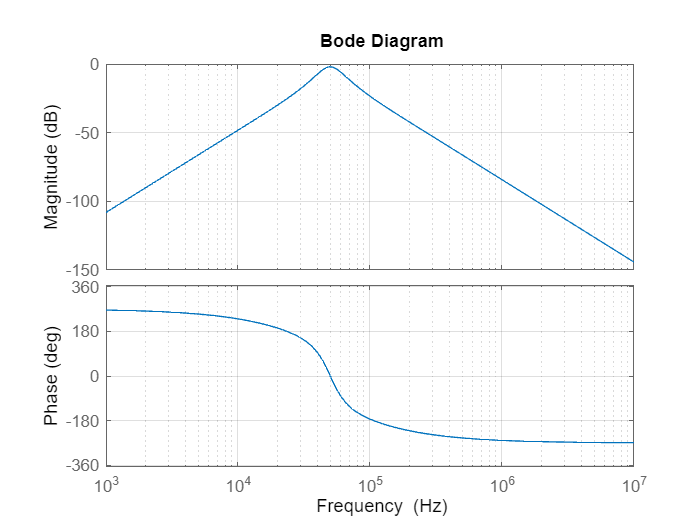

BodeDgrTest2 = bodeplot(Test2);
opt = getoptions(BodeDgrTest2);

opt.Grid = 'on';
opt.FreqUnits = 'Hz';
setoptions(BodeDgrTest2,opt);

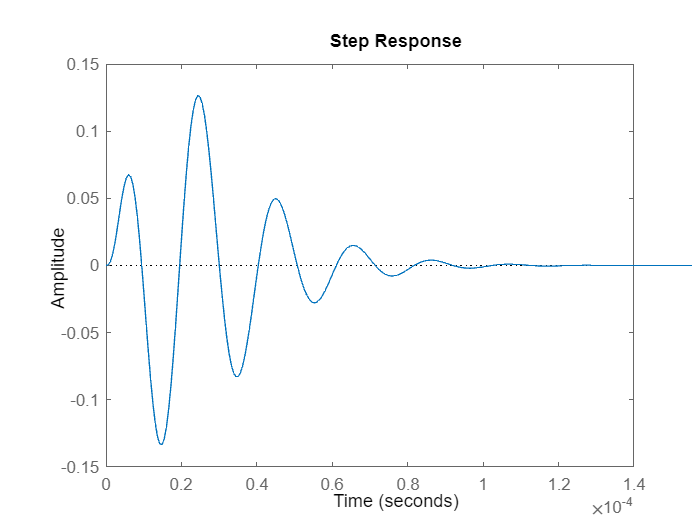

step(Test2);